## **Driver test program to check Clothoids library**

**Test clothoid**

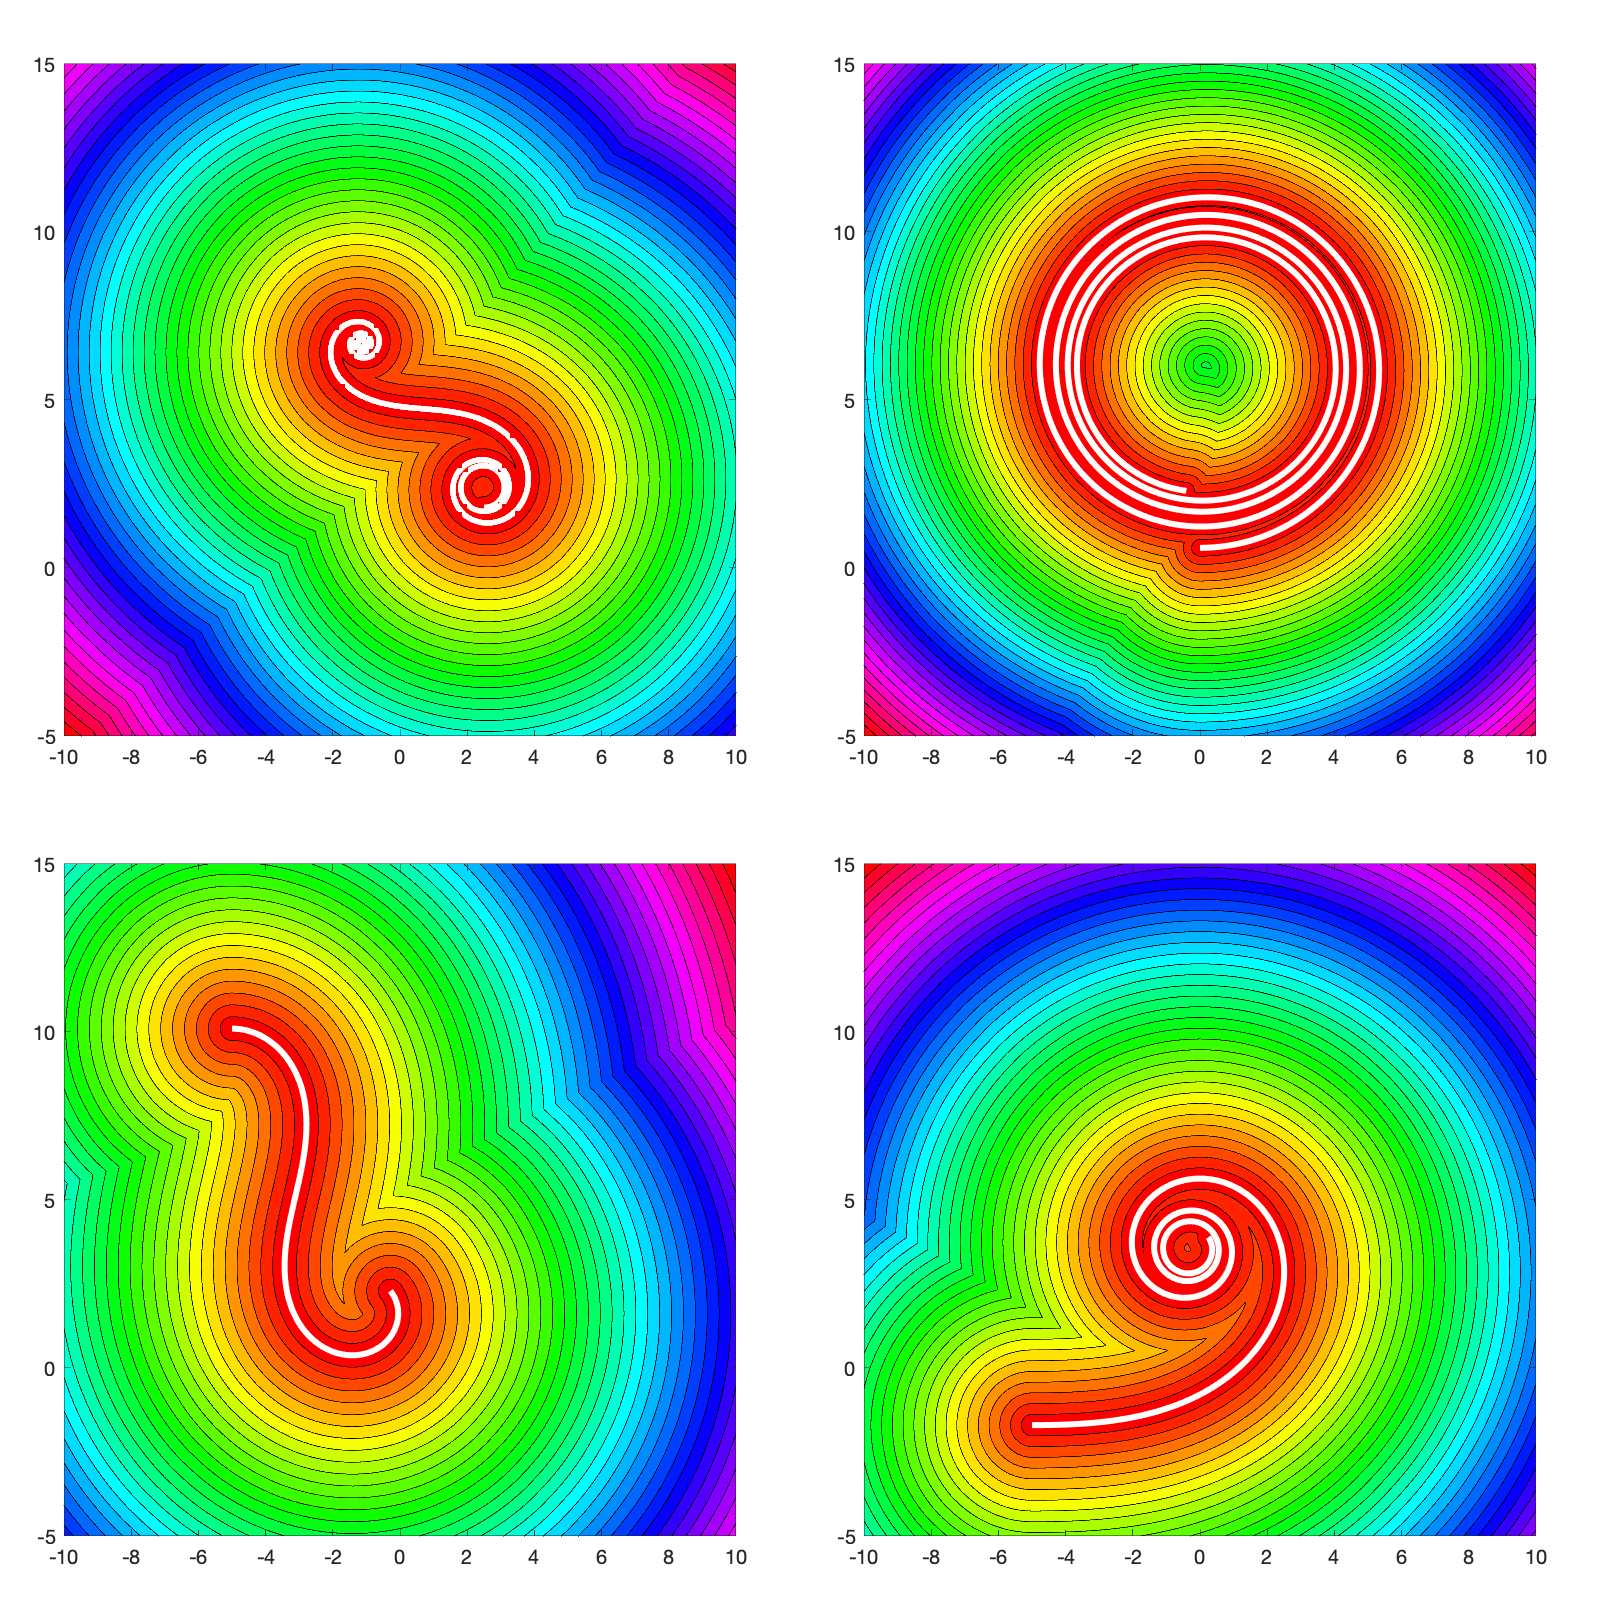

Elapsed time is 4.234831 seconds.


Elapsed time is 4.180645 seconds.


Elapsed time is 7.690113 seconds.


Elapsed time is 5.079832 seconds.


close all;

% check constructors
x0     = [-5,-5,0,2.5];
y0     = [10,-2,1,2];
theta0 = 0;
kappa0 = [-0.6, 0.025, 0.2, 2.5];
dk     = [0.1, 0.025, 0.001, -0.2];
L      = [15,40,100,30];
offs   = [0.1,0.3,-0.4,-0.2];

aa = 0.04;
bb = 0.5-2*aa;

figure('Position',[ 1 1 800 800]);

for kk=1:4

  switch(kk)
  case 1; subplot('Position',[aa aa bb bb]);
  case 2; subplot('Position',[aa+0.5 aa bb bb]);
  case 3; subplot('Position',[aa+0.5 aa+0.5 bb bb]);
  case 4; subplot('Position',[aa aa+0.5 bb bb]);
  end

  L1 = ClothoidCurve( x0(kk), y0(kk), theta0, kappa0(kk), dk(kk), L(kk) );
  %
  x     = -10:0.02:10;
  y     = -5:0.02:15;
  [X,Y] = meshgrid(x,y);

  tic
  Z = L1.distance(X,Y,offs(kk));
  toc

  colormap(hsv);
  contourf(X,Y,Z,40);
  %surf(X,Y,Z)
  axis equal;

  hold on;
  L1.plot_offs( offs(kk), 1000,'Color','white','LineWidth',3 );

  %
  L1.delete();
end